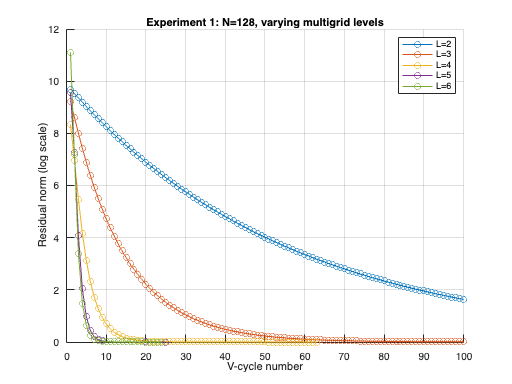

%% Experiment 1: Fixed N=128, Vary Levels
levels = 2:6;
figure('Name','Exp1: N=128, varying levels'), hold on
for L = levels
    fname = sprintf('Data/res_l%d.dat',L);
    D = load(fname);     % now reads from Data/
    semilogy(D(:,1), D(:,2), '-o', ...
        'DisplayName',sprintf('L=%d',L));
end
xlabel('V-cycle number')
ylabel('Residual norm (log scale)')
title('Experiment 1: N=128, varying multigrid levels')
legend('location','northeast')
grid on
hold off

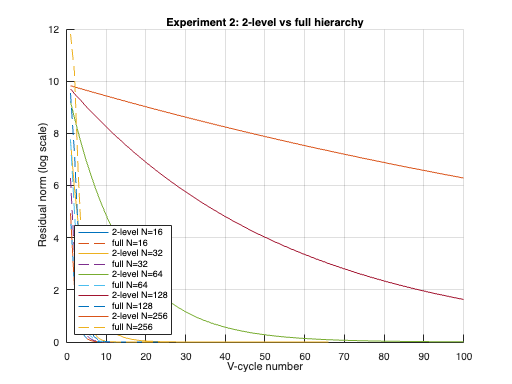


%% Experiment 2: Grid Scaling (2-level vs Full Hierarchy)
Ns = [16 32 64 128 256];
figure('Name','Exp2: grid scaling'), hold on
for N = Ns
    % 2-level data
    D2 = load(sprintf('Data/res2_%d.dat',N));
    semilogy(D2(:,1), D2(:,2), '-', ...
        'DisplayName',sprintf('2-level N=%d',N));
    % full-hierarchy data
    Df = load(sprintf('Data/resmax_%d.dat',N));
    semilogy(Df(:,1), Df(:,2), '--', ...
        'DisplayName',sprintf('full N=%d',N));
end
xlabel('V-cycle number')
ylabel('Residual norm (log scale)')
title('Experiment 2: 2-level vs full hierarchy')
legend('location','southwest')
grid on
hold off


%% Summary Table (print to console)
fprintf('Summary for Experiment 1\n');

Summary for Experiment 1


fprintf('Level  Time(s)    CoarseSolves   Cycles\n');

Level  Time(s)    CoarseSolves   Cycles


for L = levels
    txt = fileread(sprintf('Data/out_l%d.txt',L));  % stays in root
    tline = regexp(txt,'Total time: ([\d\.eE+-]+) s','tokens');
    cline = regexp(txt,'Coarse solves: (\d+)','tokens');
    D = load(sprintf('Data/res_l%d.dat',L));
    cycles = size(D,1);
    time = str2double(tline{1}{1});
    solves = str2double(cline{1}{1});
    fprintf('%2d     %8.4f    %8d       %4d\n',L,time,solves,cycles);
end

 2       0.1009         100        100
 3       0.0732         100        100
 4       0.0458          63         63
 5       0.0185          25         25
 6       0.0176          24         24



fprintf('\nSummary for Experiment 2\n');


Summary for Experiment 2


fprintf('  N    Scheme      Time(s)    CoarseSolves   Cycles\n');

  N    Scheme      Time(s)    CoarseSolves   Cycles


for N = Ns
    for scheme = {'2-level','full'}
        if strcmp(scheme,'2-level')
            txt = fileread(sprintf('Data/out2_%d.txt',N));
            D = load(sprintf('Data/res2_%d.dat',N));
        else
            txt = fileread(sprintf('Data/outmax_%d.txt',N));
            D = load(sprintf('Data/resmax_%d.dat',N));
        end
        tline = regexp(txt,'Total time: ([\d\.eE+-]+) s','tokens');
        cline = regexp(txt,'Coarse solves: (\d+)','tokens');
        cycles = size(D,1);
        time = str2double(tline{1}{1});
        solves = str2double(cline{1}{1});
        fprintf('%4d   %-10s %8.4f    %8d       %4d\n', ...
                N, scheme{1}, time, solves, cycles);
    end
end

  16   2-level      0.0003          21         21
  16   full         0.0003          21         21
  32   2-level      0.0034          66         66
  32   full         0.0011          23         23
  64   2-level      0.0203         100        100
  64   full         0.0046          24         24
 128   2-level      0.0715         100        100
 128   full         0.0186          25         25
 256   2-level      0.1751         100        100
 256   full         0.0743          26         26
